data = readtable("../Data/ENB2012_data.xlsx");

Headers = [
    "Relative Compactness"
    "Surface Area"
    "Wall Area"
    "Roof Area"
    "Overall Height"
    "Orientation"
    "Glazing Area"
    "Glazing Area Distribution"
    "Heating Load"
    "Cooling Load"]; 

data.Properties.VariableNames = Headers;
M = table2array(data);

X = [ones(size(M, 1), 1), M(:, 1:8)];
y = M(:, 9);

lambda = 0.1;
alpha = 0.46415;

% Remove feature 4 for the linear baseline to avoid rank deficiency
X_reduced = X(:, [1:3, 5:8]);

fractions = linspace(0.2, 0.8, 7);
numResamples = 50;

rng(123)

linearTrain = zeros(length(fractions), 1);
linearStdTrain = zeros(length(fractions), 1);
linearTest = zeros(length(fractions), 1);
linearStd = zeros(length(fractions), 1);

ridgeTrain = zeros(length(fractions), 1);
ridgeStdTrain = zeros(length(fractions), 1);
ridgeTest = zeros(length(fractions), 1);
ridgeStd = zeros(length(fractions), 1);

lassoTrain = zeros(length(fractions), 1);
lassoStdTrain = zeros(length(fractions), 1);
lassoTest = zeros(length(fractions), 1);
lassoStd = zeros(length(fractions), 1);

rmse = @(yTrue, yPred) sqrt(mean((yTrue(:) - yPred(:)).^2));

for i = 1:length(fractions)
    frac = fractions(i);
    linearTrainErrors = zeros(numResamples, 1);
    linearTestErrors = zeros(numResamples, 1);

    ridgeTrainErrors = zeros(numResamples, 1);
    ridgeTestErrors = zeros(numResamples, 1);

    lassoTrainErrors = zeros(numResamples, 1);
    lassoTestErrors = zeros(numResamples, 1);

    for r = 1:numResamples
        idx = randperm(size(X, 1));
        nTrain = round(frac * size(X, 1));

        trainIdx = idx(1:nTrain);
        testIdx = idx(nTrain + 1:end);

        XtrainLinear = X_reduced(trainIdx, :);
        XtestLinear = X_reduced(testIdx, :);
        YtrainLinear = y(trainIdx);
        YtestLinear = y(testIdx);

        XtrainRidge = X(trainIdx, :);
        XtestRidge = X(testIdx, :);
        YtrainRidge = y(trainIdx);
        YtestRidge = y(testIdx);

        XtrainLasso = X(trainIdx, :);
        XtestLasso = X(testIdx, :);
        YtrainLasso = y(trainIdx);
        YtestLasso = y(testIdx);

        % Linear regression: reduced feature set
        [Q, R] = qr(XtrainLinear);
        betaLinear = R \ (Q' * YtrainLinear);

        linearTrainErrors(r) = rmse(YtrainLinear, XtrainLinear * betaLinear);
        linearTestErrors(r) = rmse(YtestLinear, XtestLinear * betaLinear);

        % Ridge regression
        betaRidge = simple_ridge(XtrainRidge, YtrainRidge, lambda);

        ridgeTrainErrors(r) = rmse(YtrainRidge, XtrainRidge * betaRidge);
        ridgeTestErrors(r) = rmse(YtestRidge, XtestRidge * betaRidge);

        % LASSO regression
        [betaLasso, interceptLasso] = simple_lasso(XtrainLasso, YtrainLasso, alpha);

        trainPredLasso = XtrainLasso * betaLasso + interceptLasso;
        testPredLasso = XtestLasso * betaLasso + interceptLasso;

        lassoTrainErrors(r) = rmse(YtrainLasso, trainPredLasso);
        lassoTestErrors(r) = rmse(YtestLasso, testPredLasso);
    end

    linearTrain(i) = mean(linearTrainErrors);
    linearStdTrain(i) = std(linearTrainErrors);
    linearTest(i) = mean(linearTestErrors);
    linearStd(i) = std(linearTestErrors);

    ridgeTrain(i) = mean(ridgeTrainErrors);
    ridgeStdTrain(i) = std(ridgeTrainErrors);
    ridgeTest(i) = mean(ridgeTestErrors);
    ridgeStd(i) = std(ridgeTestErrors);

    lassoTrain(i) = mean(lassoTrainErrors);
    lassoStdTrain(i) = std(lassoTrainErrors);
    lassoTest(i) = mean(lassoTestErrors);
    lassoStd(i) = std(lassoTestErrors);
end

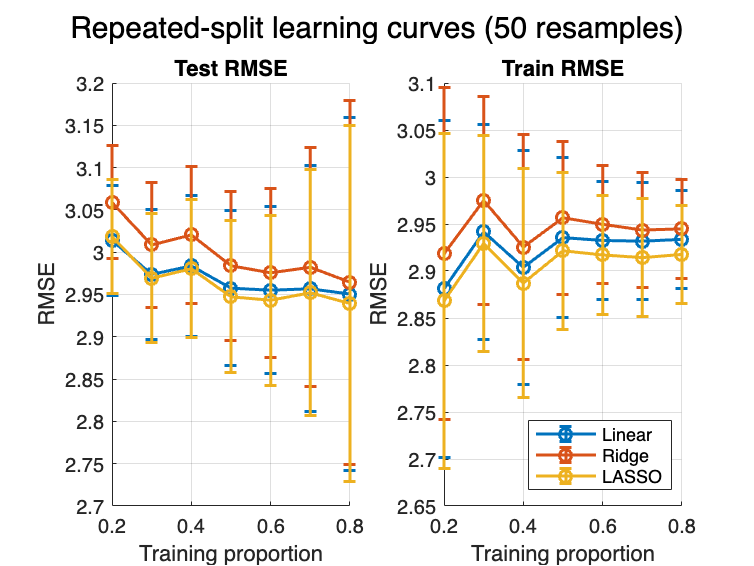

figure()

ax1 = subplot(1, 2, 1);
hold on;
errorbar(fractions, linearTest, linearStd, 'o-',  'LineWidth', 1.5);
errorbar(fractions, ridgeTest,  ridgeStd,  'o-',  'LineWidth', 1.5);
errorbar(fractions, lassoTest,  lassoStd,  'o-',  'LineWidth', 1.5);
hold off;
xlabel('Training proportion');
ylabel('RMSE');
title('Test RMSE');
grid on;

ax2 = subplot(1, 2, 2);
hold on;
errorbar(fractions, linearTrain, linearStdTrain, 'o-', 'LineWidth', 1.5);
errorbar(fractions, ridgeTrain, ridgeStdTrain,  'o-', 'LineWidth', 1.5);
errorbar(fractions, lassoTrain, lassoStdTrain,  'o-', 'LineWidth', 1.5);
hold off;
xlabel('Training proportion');
ylabel('RMSE');
title('Train RMSE');
grid on;

legend(ax2, {'Linear', 'Ridge', 'LASSO'}, 'Location', 'southeast');

sgtitle('Repeated-split learning curves (' + string(numResamples) + ' resamples)');


T = table( ...
    fractions(:), ...
    linearTest(:), linearStd(:), ...
    ridgeTest(:), ridgeStd(:), ...
    lassoTest(:), lassoStd(:), ...
    'VariableNames', { ...
        'Fraction', ...
        'Linear_RMSE', 'Linear_Std', ...
        'Ridge_RMSE', 'Ridge_Std', ...
        'LASSO_RMSE', 'LASSO_Std' ...
    })

T = 7×7 table
    Fraction    Linear_RMSE    Linear_Std    Ridge_RMSE    Ridge_Std    LASSO_RMSE    LASSO_Std
    ________    ___________    __________    __________    _________    __________    _________
      0.2          3.014        0.064893       3.0588      0.066789       3.0185      0.066996 
      0.3         2.9738        0.077141       3.0085      0.073419       2.9692      0.076015 
      0.4         2.9838        0.083375       3.0205      0.081156       2.9805      0.081626 
      0.5         2.9575        0.091902        2.984      0.088323       2.9473      0.089919 
      0.6         2.9551        0.098875       2.9756      0.099583       2.9432       0.10024 
      0.7         2.9567         0.14545       2.9822       0.14125        2